filename = "/Users/vysakhpr/Documents/Coursera/Deep Learning for Computer Vision/Data/MathWorks Created/ASL Alphabet/Classification/Test";
imdsTest = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource","foldernames");
filename = "/Users/vysakhpr/Documents/Coursera/Deep Learning for Computer Vision/Data/MathWorks Created/ASL Alphabet/Classification/Train";
imdsASL = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

[imdsTrain, imdsVal] = splitEachLabel(imdsASL, 0.8, "randomized");

size(imdsTest.Files)

ans =    240     1


size(imdsVal.Files)

ans =    120     1


countEachLabel(imdsVal)

ans = 24×2 table
    Label    Count
    _____    _____

      A        5  
      B        5  
      C        5  
      D        5  
      E        5  
      F        5  
      G        5  
      H        5  
      I        5  
      K        5  
      L        5  
      M        5  
      N        5  
      O        5  
      P        5  
      Q        5  


imdsASL.readimage(1)

ans = 300×300×3 uint8 array
ans(:,:,1) =

   140   140   139   140   140   141   142   142   142   141   140   140   137   137   140   139   139   138   142   141   142   142   142   143   142   139   139   140   140   141   142   142   144   144   146   145   144   144   144   144   143   144   144   144   144   144   143   144   147   146   145   146   145   145   143   144   144   144   146   144   145   145   149   150   147   145   146   147   149   149   149   148   147   147   149   148   146   146   150   148   147   147   149   149   149   149   147   150   149   148   148   149   151   150   148   150   147   148   150   149   149   148   151   150   152   153   153   153   151   148   149   149   149   150   150   152   149   151   150   149   152   151   150   150   152   152   156   153   152   150   152   150   152   150   151   153   151   151   155   152   152   151   152   151   152   153   156   155   155   155   153   150   149   151   155   156   154   153   155   1

netv3 = inceptionv3;

lgraph = layerGraph(netv3);
lgraph.Layers(end-2)

ans =   FullyConnectedLayer with properties:

          Name: 'predictions'

   Hyperparameters
     InputSize: 2048
    OutputSize: 1000

   Learnable Parameters
       Weights: [1000×2048 single]
          Bias: [1000×1 single]

  Show all properties


fclayer = lgraph.Layers(end-2);
lgraph = replaceLayer(lgraph, fclayer.Name, fullyConnectedLayer(24, 'Name', "NewFC"));
classlayer = lgraph.Layers(end);
lgraph = replaceLayer(lgraph, classlayer.Name, classificationLayer('Name', 'NewClass'));



augTrain = augmentedImageDatastore(netv3.Layers(1).InputSize, imdsTrain);
augVal = augmentedImageDatastore(netv3.Layers(1).InputSize, imdsVal);
augTest = augmentedImageDatastore(netv3.Layers(1).InputSize, imdsTest);

opts = trainingOptions("adam", "Shuffle","every-epoch", "Plots","training-progress", "OutputNetwork","best-validation", "ValidationData",augVal, "ValidationFrequency",5);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:36 |        3.91% |       21.67% |       3.2765 |       2.9605 |          0.0010 |
|       2 |           5 |       00:02:23 |       74.22% |       60.83% |       1.1948 |       1.3088 |          0.0010 |
|       4 |          10 |       00:04:29 |       96.09% |       84.17% |       0.1446 |       0.5011 |          0.0010 |
|       5 |          15 |       00:06:38 |       95.31% |       87.50% |       0.1907 |   

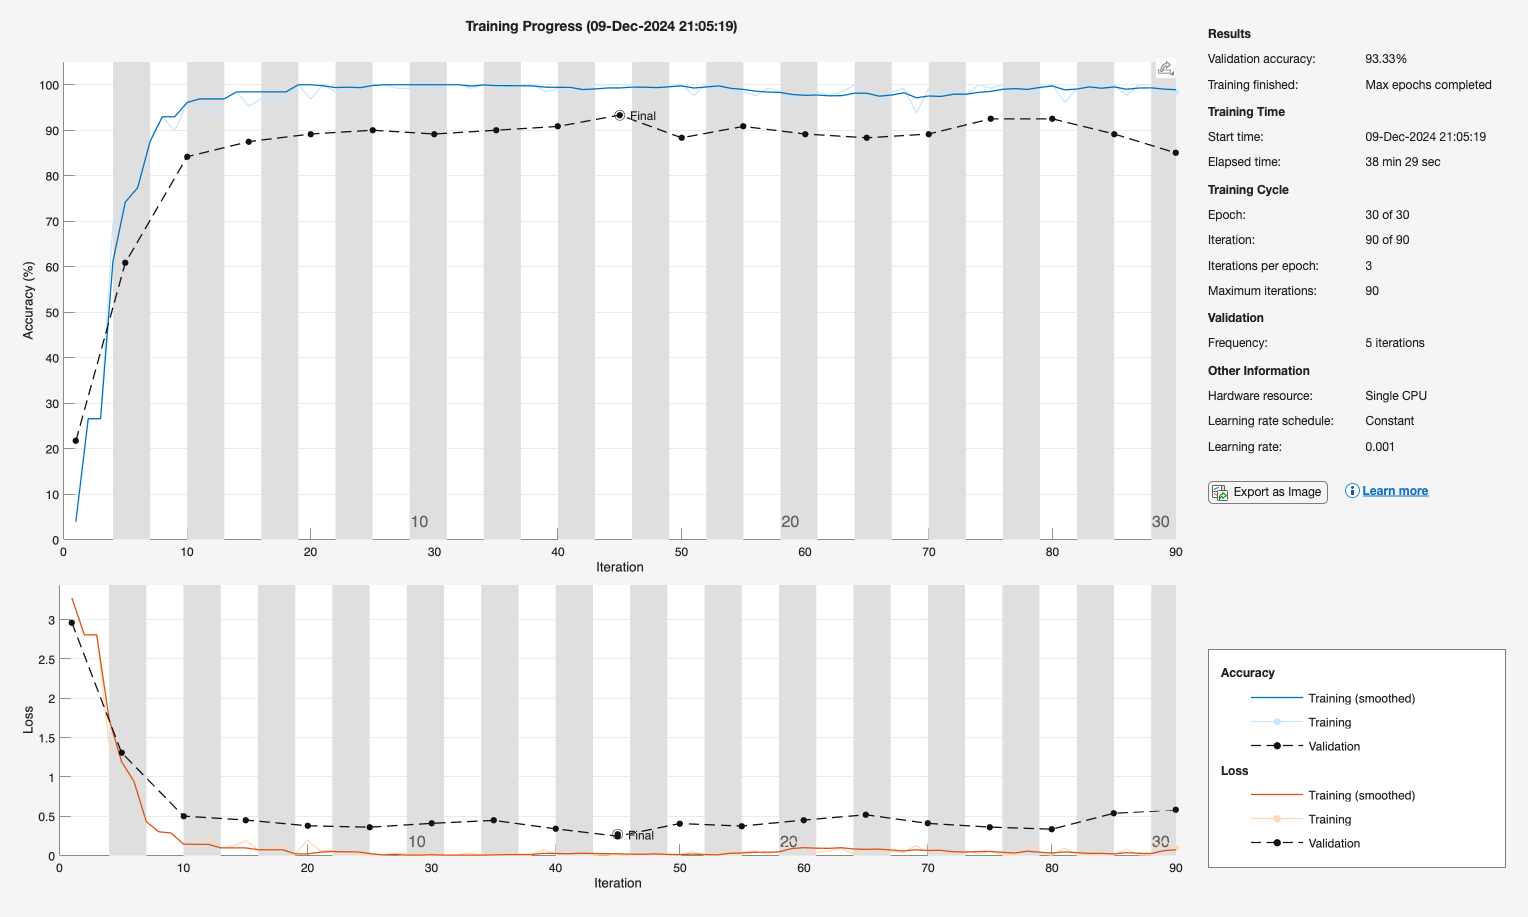

net = trainNetwork(augTrain, lgraph, opts);

[preds, scores] = classify(net, augTest);

accuracy = nnz(preds == imdsTest.Labels)/length(preds)

accuracy = 0.9167

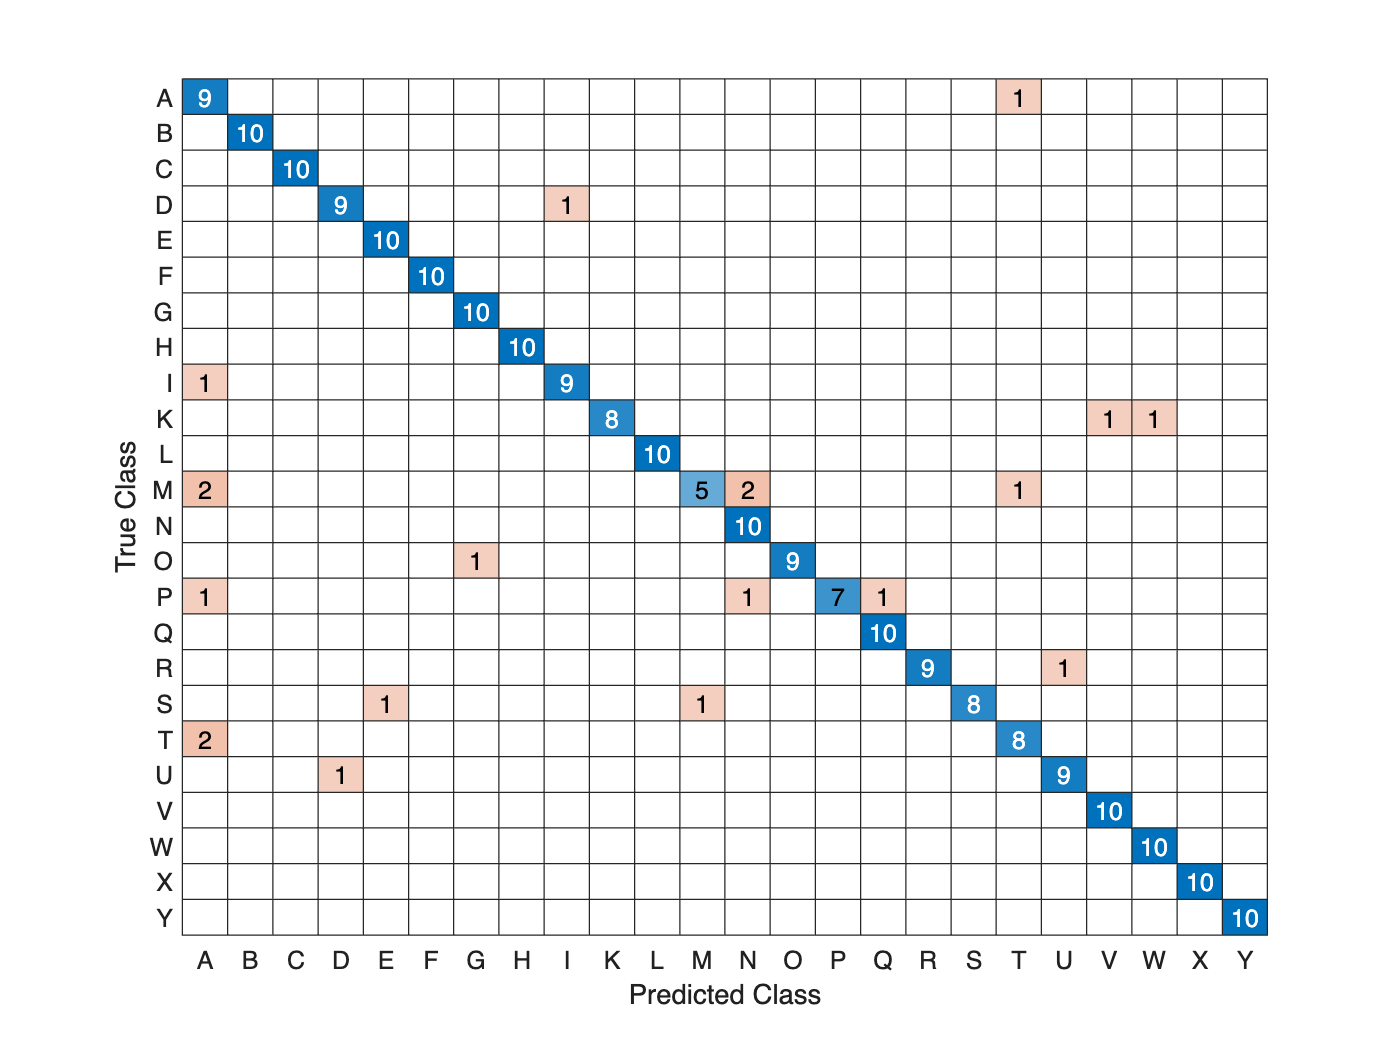

confusionchart(imdsTest.Labels, preds)

testASLmodel(net)

Congratulations on training an accurate model!
Your answer code is: 23061912


filename = "/Users/vysakhpr/Documents/Coursera/Deep Learning for Computer Vision/Data/MathWorks Created/ASL Alphabet/Classification/Unlabeled";
imdsUnlabeled = imageDatastore(filename, "IncludeSubfolders",true, "LabelSource","foldernames");

augUnlabeled = augmentedImageDatastore(netv3.Layers(1).InputSize, imdsUnlabeled);

[preds, score] = classify(net, augUnlabeled);

preds

preds = 9×1 categorical array
     H 
     R 
     E 
     A 
     T 
     V 
     C 
     V 
     K 


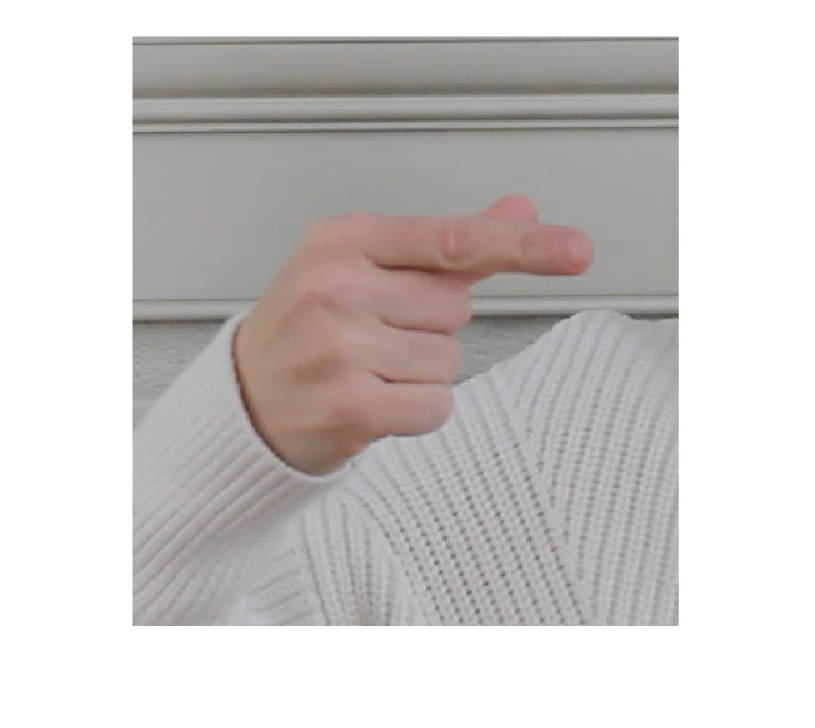

imshow(imdsUnlabeled.readimage(1))